# Michelson interferometer example

% Jonghwan Lee, Apr 2021

All lengths are in [m].

clear

c = 3e8;
eps0 = 8.85e-12;

n = 1;
E0 = 1.0;
L = 50e-3;
lam0 = 1000e-9;
fwhmLam = 100e-9;
R = 1;

dz = 0.01e-6;
z = L + (-10e-6:dz:10e-6);

Obtain the interference pattern.

`k0` = $k(\omega_0)$

`kp0` = $k'(\omega_0)$

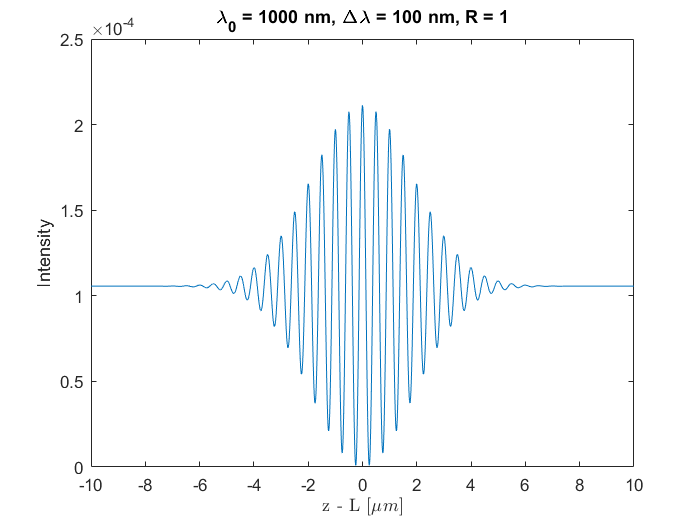

k0 = 2*pi/lam0;  % center wavenumber
w0 = c * k0;
kp0 = 1/c;
fwhmOmega = fwhmLam/lam0 * w0;  % approximately
sigmaOmega = fwhmOmega / (2*sqrt(2*log(2)));
    
I1 = 1 + abs(R)^2 + 2 * abs(R) * ... 
    exp( -2 * sigmaOmega^2 * kp0^2 * (z-L).^2 ) ...
    .* cos( 2 * k0 * (z-L) + angle(R) );

I = 1/16/pi*n*c*eps0*E0^2 * I1;

figure
plot((z-L)*1e6,I)
xlim([-10 10])
xlabel('z - L [$\mu m$]','Interpreter',"latex")
ylabel('Intensity')
title(['\lambda_0 = ' num2str(lam0*1e9) ' nm, \Delta\lambda = ' num2str(fwhmLam*1e9) ' nm, R = ' num2str(R)])    

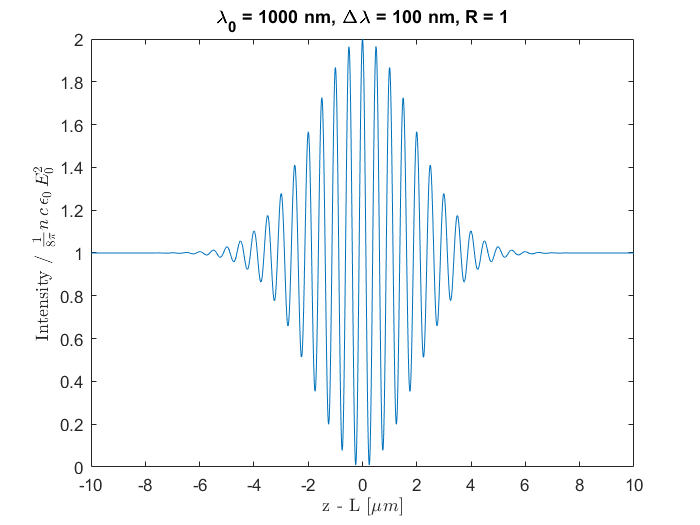


I = I1/2;  % intensity as a unit of 1/8/pi*n*c*eps0*E0^2

figure
plot((z-L)*1e6,I)
xlim([-10 10])
xlabel('z - L [$\mu m$]','Interpreter',"latex")
ylabel('Intensity / $ \frac{1}{8 \pi} n \, c \, \epsilon_0 \, E_0^2 $','Interpreter',"latex")
title(['\lambda_0 = ' num2str(lam0*1e9) ' nm, \Delta\lambda = ' num2str(fwhmLam*1e9) ' nm, R = ' num2str(R)])    